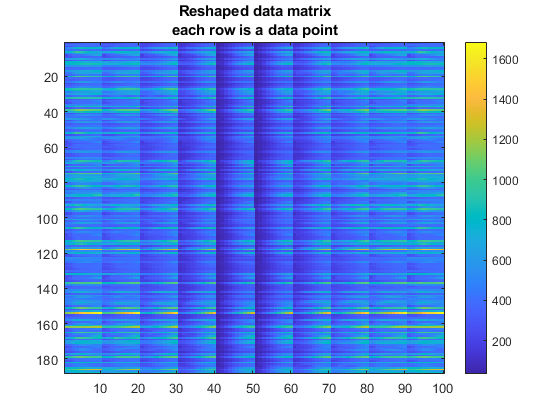

clear; close all;

% data = load("C:\Users\alex\OneDrive - California Institute of Technology\Documents\Graduate\Research\2D-dispersion\OUTPUT\IBZ surface 3 output 11-Nov-2020 21-11-32\DATA N_struct100 RNG_offset0 11-Nov-2020 21-11-32.mat",'EIGENVALUE_DATA','WAVEVECTOR_DATA','CONSTITUTIVE_DATA');
data = load("C:\Users\alex\OneDrive - California Institute of Technology\Documents\Graduate\Research\2D-dispersion\OUTPUT\FOR COVAR EXPER output 02-Dec-2020 15-29-25\DATA N_struct188 RNG_offset0 02-Dec-2020 15-29-25.mat",'EIGENVALUE_DATA','WAVEVECTOR_DATA','CONSTITUTIVE_DATA');

struct_idx = 1;
eig_idx = 1;

EIGENVALUE_DATA = data.EIGENVALUE_DATA;
WAVEVECTOR_DATA = data.WAVEVECTOR_DATA;

% EIGENVALUE_DATA = reshape(EIGENVALUE_DATA,100,8,60,60);
% EIGENVALUE_DATA = permute(EIGENVALUE_DATA,[1 2 4 3]);
% EIGENVALUE_DATA = reshape(EIGENVALUE_DATA,100,8,3600);

orig_dom_X1 = linspace(-pi,pi,10);%WAVEVECTOR_DATA(1,1,1:60);
orig_dom_Y1 = linspace(0,pi,10);

imagesc(squeeze(EIGENVALUE_DATA(:,eig_idx,:))')
colorbar
title(['Reshaped data matrix' newline 'each row is a data point'])

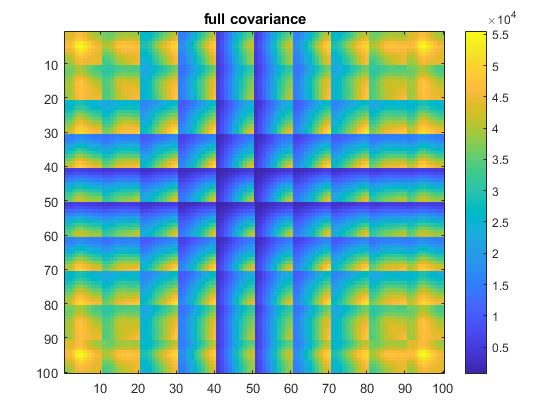


covariance = cov(squeeze(EIGENVALUE_DATA(:,eig_idx,:))');

imagesc(covariance)
colorbar
title('full covariance')

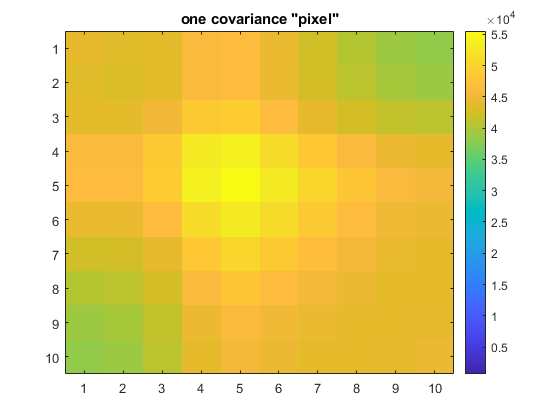

cax = caxis;

imagesc(covariance(1:10,1:10))
colorbar
title('one covariance "pixel"')
caxis(cax);

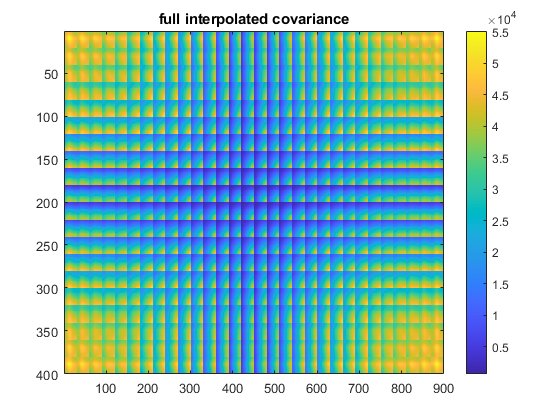


N_h = 20;
M_h = 30;

new_dom_X1 = linspace(-pi,pi,N_h);
new_dom_Y1 = linspace(0,pi,N_h);
new_dom_X2 = linspace(-pi,pi,M_h);
new_dom_Y2 = linspace(0,pi,M_h);

idxs = (repmat(1:10,1,10) - 1)*10 + ceil((1:100)/10);

wv_orig = WAVEVECTOR_DATA(:,:,1);
wv_orig = wv_orig(idxs,:);
x_orig = linspace(0,1,size(wv_orig,1));

[X1_h,Y1_h] = ndgrid(new_dom_X1,new_dom_Y1);
wv_1 = reshape(permute(cat(3,X1_h,Y1_h),[3 1 2]),2,[])';

[X2_h,Y2_h] = ndgrid(new_dom_X2,new_dom_Y2);
wv_2 = reshape(permute(cat(3,X2_h,Y2_h),[3 1 2]),2,[])';

covariance_interp = covariance_function(wv_1,wv_2,orig_dom_X1,orig_dom_Y1,covariance);

imagesc(covariance_interp)
colorbar
title('full interpolated covariance')

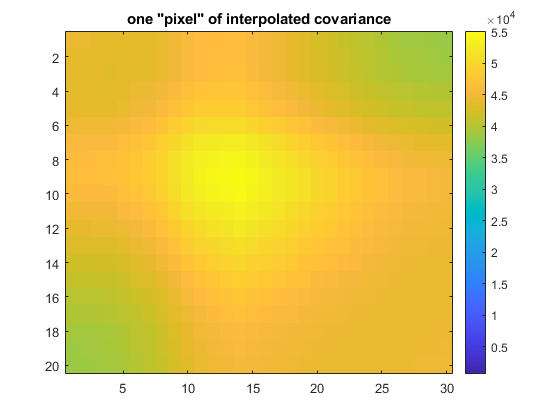

cax = caxis;

imagesc(covariance_interp(1:N_h,1:M_h))
colorbar
title('one "pixel" of interpolated covariance')
caxis(cax)


test_idx1 = 50

test_idx1 = 50

test_idx2 = 61

test_idx2 = 61

wv_test1 = wv_orig(test_idx1,:)

wv_test1 =     3.1416    1.3963


wv_test2 = wv_orig(test_idx2,:)

wv_test2 =    -3.1416    2.0944



covariance(test_idx1,test_idx2)

ans = 1.4205e+04


covariance_test = covariance_function(wv_test1,wv_test2,orig_dom_X1,orig_dom_Y1,covariance);
covariance_test

covariance_test = 1.4205e+04

disp('break')

break



test_idx11 = 49; test_idx12 = 40; %50
test_idx21 = 61; test_idx22 = 72; %62
wv_orig(test_idx11,:)

ans =     2.4435    1.3963


wv_orig(test_idx12,:)

ans =     3.1416    1.0472


wv_test1 = mean([wv_orig(test_idx11,:);wv_orig(test_idx12,:)],1)

wv_test1 =     2.7925    1.2217


wv_orig(test_idx21,:)

ans =    -3.1416    2.0944


wv_orig(test_idx22,:)

ans =    -2.4435    2.4435


wv_test2 = mean([wv_orig(test_idx21,:);wv_orig(test_idx22,:)],1)

wv_test2 =    -2.7925    2.2689



est1 = covariance(test_idx11,test_idx21)

est1 = 1.3706e+04

est2 = covariance(test_idx11,test_idx22)

est2 = 2.3151e+04

est3 = covariance(test_idx12,test_idx21)

est3 = 1.6261e+04

est4 = covariance(test_idx12,test_idx22)

est4 = 2.7641e+04

mean([est1 est2 est3 est4])

ans = 2.0190e+04

covariance_test = covariance_function(wv_test1,wv_test2,orig_dom_X1,orig_dom_Y1,covariance)

covariance_test = 2.0157e+04